clearvars
cd('G:\AR2\Crc\ClimateUnit\Projects\EDIS\jenmatlab\OAI_station_compare')
load OW_OAI_AWS.mat
load OAI_atmos41.mat
load BoM_OAI_manual.mat

## clean up missing vals

atmos41data.WindSpeedms(atmos41data.WindSpeedms<0)=NaN;
atmos41data.WindDirectiondeg(atmos41data.WindDirectiondeg<0)=NaN;   
atmos41data.AtmosPressurekPa(atmos41data.AtmosPressurekPa==0)=NaN;


## Daily Resample

atmos41data.Timestamps.TimeZone='Australia/Sydney';
OWdata.Time.TimeZone='Australia/Sydney';

T41sum=retime(atmos41data,'daily','sum');
T41mean=retime(atmos41data,'daily','mean');
T41min=retime(atmos41data,'daily','min');
T41max=retime(atmos41data,'daily','max');
% nansum returns 0 if all elements are NaN.  find aggregations where all
% elements are NaN and replace with NaN
allnan=retime(atmos41data,'daily',@(x) all(isnan(x)));
atmos41varnames=atmos41data.Properties.VariableNames;
for i=1:size(atmos41data,2)
    T41sum.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
    T41mean.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
    T41min.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
    T41max.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
end

TOWsum=retime(OWdata,'daily','sum');
TOWmean=retime(OWdata,'daily','mean');
TOWmin=retime(OWdata,'daily','min');
TOWmax=retime(OWdata,'daily','max');


TBoM=retime(BoMdata,T41sum.Timestamps);
TBoM.meanT = mean(TBoM{:,1:2},2);

## formatting

%colors
A41C=[0 0.4470 0.7410];
BoMC=[0.9290 0.6940 0.1250];
OWC=[0.8500 0.3250 0.0980];
%fontsize 
fs=16;
%transparency
a=.6;


## Data availability

figure
% plot(T41mean.Timestamps,T41sum.Precipitationmm./T41sum.Precipitationmm,'color',A41C,'linewidth',3)
hold on
plot(atmos41data.Timestamps,ones(size(atmos41data,1)))
% plot(TOWmean.Timestamps,T41sum.Precipitationmm./T41sum.Precipitationmm,'color',A41C,'linewidth',3)
% plot(T41mean.Timestamps,T41sum.Precipitationmm./T41sum.Precipitationmm,'color',A41C,'linewidth',3)

## min Temperature

No histograms in report since analysis period is not the same?  biases exist.

bins=25;
figure
sgtitle('Daily Minimum Temperature')
% set(gcf,'Visible','on')
subplot(1,3,1)
p1=histogram(T41min.AirTempdegC,bins,'FaceAlpha',a,'FaceColor',A41C);
hold on
% line([nanmedian(T41min.AirTempdegC),nanmedian(T41min.AirTempdegC)], ylim,'linestyle','--', 'LineWidth', 2, 'Color', 'k')
set(gca,'xlim',[-5 22],'xtick',[-5:5:20])
xlabel('Temperature {\circ}C')
ylabel('Frequency')
title('Atmos41')


subplot(1,3,2)
p2=histogram(TOWmin.AirTemperature,bins,'FaceAlpha',a,'FaceColor',OWC);
hold on
% line([nanmedian(TOWmin.AirTemperature),nanmedian(TOWmin.AirTemperature)], ylim,'linestyle','--', 'LineWidth', 2, 'Color', 'k')
title('Office of Water')
set(gca,'xlim',[-5 22],'xtick',[-5:5:20])
xlabel('Temperature {\circ}C')


subplot(1,3,3)
p5=histogram(TBoM.MinimumTemperatureC,bins,'FaceAlpha',a,'facecolor',BoMC);
hold on
% lm=line([nanmedian(TBoM.MinimumTemperatureC),nanmedian(TBoM.MinimumTemperatureC)], ylim,'linestyle','--', 'LineWidth', 2, 'Color', 'k');
% ls1=line([nanstd(TBoM.MinimumTemperatureC),nanstd(TBoM.MinimumTemperatureC)], ylim,'linestyle',':', 'LineWidth', 2, 'Color', 'k');
% ls2=line([-nanstd(TBoM.MinimumTemperatureC),-nanstd(TBoM.MinimumTemperatureC)], ylim,'linestyle',':', 'LineWidth', 2, 'Color', 'k');

title('BoM')
set(gca,'xlim',[-10 25],'xtick',[-5:5:20])
xlabel('Temperature {\circ}C')


% 
% mnlabel = sprintf('Mean -- %3.2d', mn);   
% stdlabel = sprintf('Std Deviation -- %3.2d', stdv);
% klabel = sprintf('Kurtosis -- %3.2d', k);
% %%%Create the textbox
% h = annotation('textbox',[0.58 0.75 0.1 0.1]);
% set(h,'String',{mnlabel,stdlabel,klabel});


## Max Temp

% figure
% % legend('Atmos41','Office of Water','BoM')
% % set(ph1,'facecolor','b')
% % title('Daily Minimum Temperatures','fontsize',fs)
% subplot(1,2,2)
% p3=histogram(T41max.AirTempdegC,20,'FaceAlpha',a);
% hold on
% p4=histogram(TOWmax.AirTemperature,20,'FaceAlpha',a);
% p6=histogram(TBoM.MaximumTemperatureC,20,'FaceAlpha',a);
% legend('Atmos41','Office of Water','BoM')
% % set(ph2,'facecolor','r')
% title('Daily Maximum Temperatures','fontsize',fs)

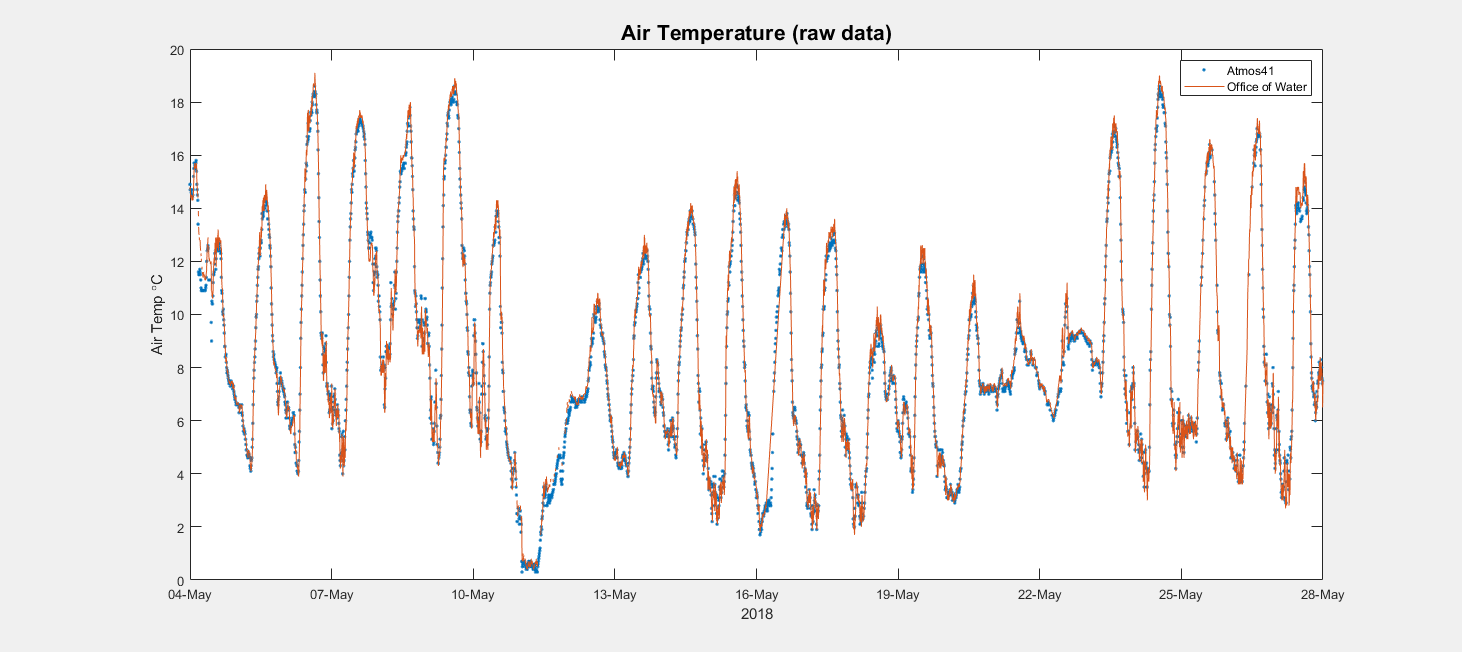


figure('position',[98         686        1462         652])
set(gcf,'visible','on')
p=plot(atmos41data.Timestamps,atmos41data.AirTempdegC,'.',OWdata.Time,OWdata.AirTemperature);
legend('Atmos41','Office of Water')
title('Air Temperature (raw data)','fontsize',fs)
ylabel('Air Temp {\circ}C')
xlabel('2018')
 set(gca,'xlim',[datetime(2018,5,1,'timezone','UTC') datetime(2018,5,30,'timezone','UTC')])
 datetick('x','dd-mmm','keepticks')
 print(gcf, 'figs/atmos41vsOoW_airtemp_may','-dpng','-r100')

## Temperature Correlations

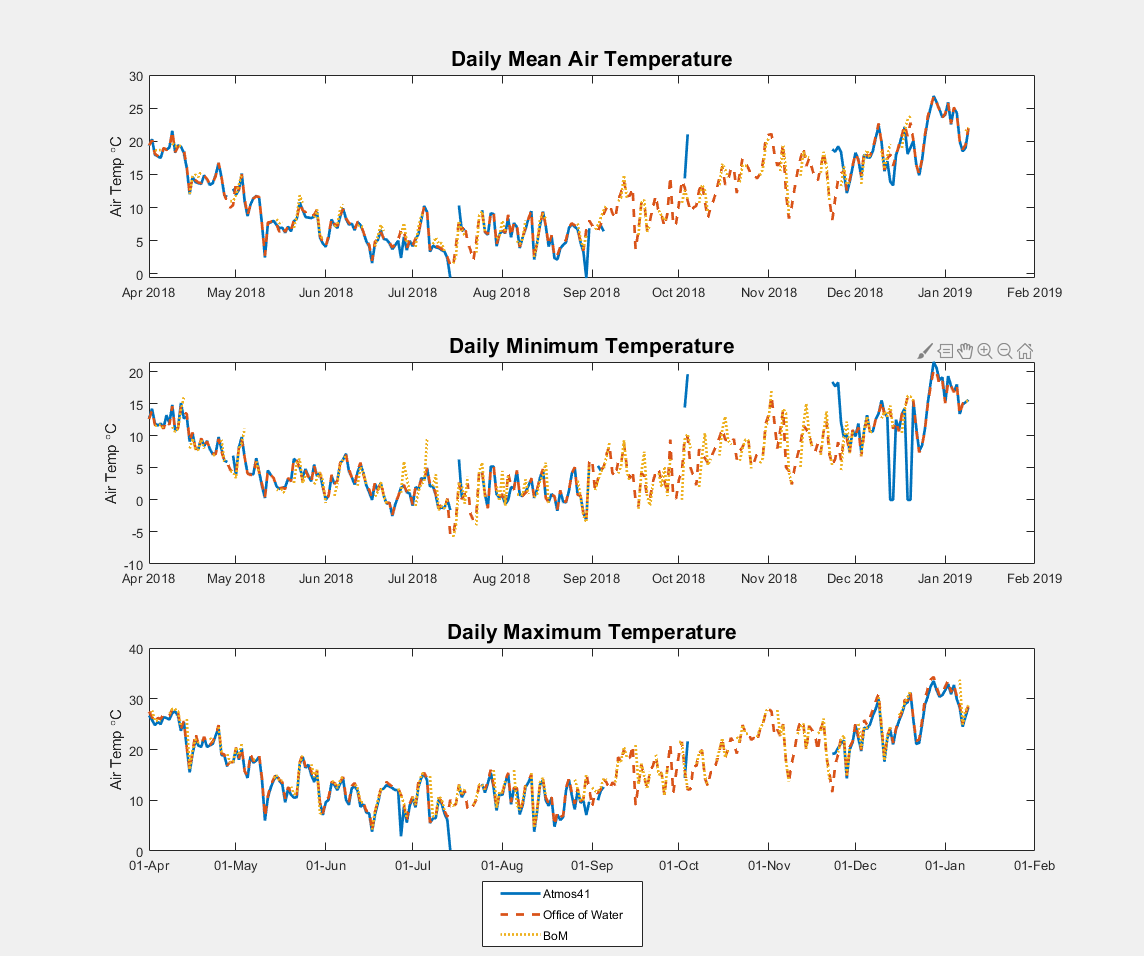

lw=2;
figure('position',[1000         382        1144         956])
set(gcf,'Visible','on')
subplot(3,1,1)
a1=gca;
p1=plot(T41mean.Timestamps,T41mean.AirTempdegC,TOWmean.Time,TOWmean.AirTemperature,'--' ,TBoM.Time,TBoM.meanT,':','linewidth',2);
title('Daily Mean Air Temperature','fontsize',fs)
ylabel('Air Temp {\circ}C')
subplot(3,1,2)
a2=gca;
plot(T41min.Timestamps,T41min.AirTempdegC,TOWmin.Time,TOWmin.AirTemperature,'--',TBoM.Time,TBoM.MinimumTemperatureC,':','linewidth',2);
% legend('Atmos41','Office of Water','BoM')
title('Daily Minimum Temperature','fontsize',fs)
ylabel('Air Temp {\circ}C')
subplot(3,1,3)
a3=gca;
plot(T41max.Timestamps,T41max.AirTempdegC,TOWmax.Time,TOWmax.AirTemperature,'--',TBoM.Time,TBoM.MaximumTemperatureC,':','linewidth',2);
% legend('Atmos41','Office of Water','BoM')
title('Daily Maximum Temperature','fontsize',fs)
ylabel('Air Temp {\circ}C')

linkaxes([a1 a2 a3],'x')
%  set(gca,'xlim',[datetime(2018,5,1,'timezone','UTC') datetime(2018,5,30,'timezone','UTC')])
 datetick('x','dd-mmm','keepticks')
 hl=legend('Atmos41','Office of Water','BoM');
 set(hl,'position',[0.4213    0.0098    0.1406    0.0687])
 print(gcf, 'figs/dailyminmaxtempv2','-dpng','-r100')

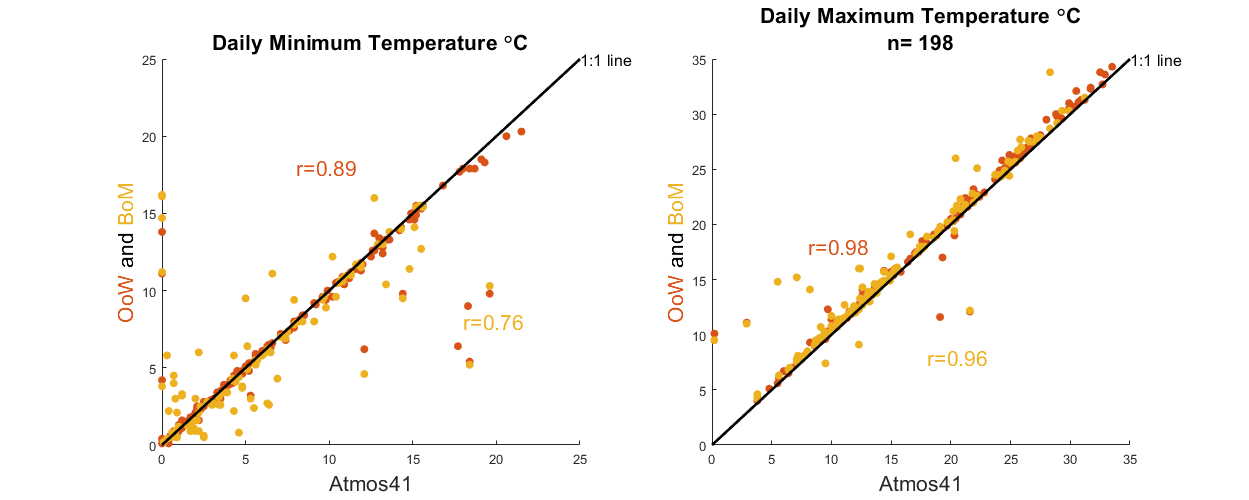


figure('Position',[498          38        1249        500])
% set(gcf,'Visible','on')
subplot(1,2,1)

s1=scatter(T41min.AirTempdegC,TOWmin.AirTemperature,'filled','markerfacecolor',OWC);
hold on
s2=scatter(T41min.AirTempdegC,TBoM.MinimumTemperatureC,'filled','markerfacecolor',BoMC);
title('Daily Minimum Temperature {\circ}C','fontsize',fs)
hold on
%plot 1:1 line
x=0:25;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,~]=corrcoef(T41min.AirTempdegC,TOWmin.AirTemperature,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
[r2,~]=corrcoef(T41min.AirTempdegC,TBoM.MinimumTemperatureC,'rows','complete');
Y2 = sprintf('%.2f',r2(1,2));
string2=['r=' Y2];
text(8,18,string,'fontsize',fs,'color',OWC)
text(18,8,string2,'fontsize',fs,'color',BoMC)

% ylabel('OoW and BoM')
ylabel( sprintf('%s%s{%f %f %f}OoW %sand %s{%f %f %f}BoM', '\fontsize{16}', '\color[rgb]', OWC, '\color{black}', '\color[rgb]', BoMC),'fontweight','bold')
xlabel('Atmos41','FontWeight','bold','fontsize',16)
set(gca,'xlim',[ 0 max(x)],'ylim',[ 0 max(y)]);




subplot(1,2,2)
s1=scatter(T41max.AirTempdegC,TOWmax.AirTemperature,'filled','markerfacecolor',OWC);
hold on
s2=scatter(T41max.AirTempdegC,TBoM.MaximumTemperatureC,'filled','markerfacecolor',BoMC);
title({'Daily Maximum Temperature {\circ}C',['n= ' num2str(sum(~isnan(T41max.AirTempdegC)))] },'fontsize',fs)
hold on
%plot 1:1 line
x=0:35;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,~]=corrcoef(T41max.AirTempdegC,TOWmax.AirTemperature,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
[r2,~]=corrcoef(T41max.AirTempdegC,TBoM.MaximumTemperatureC,'rows','complete');
Y2 = sprintf('%.2f',r2(1,2));
string2=['r=' Y2];
text(8,18,string,'fontsize',fs,'color',OWC)
text(18,8,string2,'fontsize',fs,'color',BoMC)

% ylabel('OoW and BoM')

ylabel( sprintf('%s%s{%f %f %f}OoW %sand %s{%f %f %f}BoM', '\fontsize{16}', '\color[rgb]', OWC, '\color{black}', '\color[rgb]', BoMC),'fontweight','bold')
xlabel('Atmos41','FontWeight','bold','fontsize',fs)
set(gca,'xlim',[ 0 max(x)],'ylim',[ 0 max(y)]);
print(gcf, 'figs/dailytemp_corr','-dpng','-r100')

## Solar Radiation


figure
% set(gcf,'Visible','on')
p=plot(T41mean.Timestamps,T41mean.SolarRadiationWm2,TOWmean.Time,TOWmean.GlobalRadWSqM );
legend('Atmos41','Office of Water')
title('Solar Radiation','fontsize',fs)
ylabel('W/m^2')

## Rainfall

prcpcombo=[T41sum.Precipitationmm,TOWsum.Rainfallmm,TBoM.Rainfallmm];

figure('Position',[242          25        2076        813])
set(gcf,'visible','on')
plot(T41sum.Timestamps,prcpcombo,'linewidth',2)
legend('Atmos41','Office of Water','BoM')
%  set(gca,'xlim',[datetime(2018,5,1,'timezone','UTC') datetime(2018,8,30,'timezone','UTC')])
 datetick('x','dd-mmm','keepticks')
title(['Daily Total Rainfall'])
ylabel('Rainfall (mm)')
print(gcf, 'figs/dailytotalrainfall_timeseries','-dpng','-r100')

figure('Position',[498          38        800        500])
set(gcf,'Visible','on')


s1=scatter(T41sum.Precipitationmm,TOWsum.Rainfallmm,'filled','markerfacecolor',OWC);
hold on
s2=scatter(T41sum.Precipitationmm,TBoM.Rainfallmm,'filled','markerfacecolor',BoMC);
title('Daily Total Rainfall','fontsize',fs)
hold on
%plot 1:1 line
x=0:36;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,~]=corrcoef(T41sum.Precipitationmm,TOWsum.Rainfallmm,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
[r2,~]=corrcoef(T41sum.Precipitationmm,TBoM.Rainfallmm,'rows','complete');
Y2 = sprintf('%.2f',r2(1,2));
string2=['r=' Y2];
text(8,18,string,'fontsize',fs,'color',OWC)
text(18,8,string2,'fontsize',fs,'color',BoMC)

% ylabel('OoW and BoM')
ylabel( sprintf('%s%s{%f %f %f}OoW %sand %s{%f %f %f}BoM', '\fontsize{16}', '\color[rgb]', OWC, '\color{black}', '\color[rgb]', BoMC),'fontweight','bold')
xlabel('Atmos41','FontWeight','bold','fontsize',16)
set(gca,'xlim',[ 0 max(x)],'ylim',[ 0 max(y)]);
print(gcf, 'figs/dailytotalrainfall_scatter','-dpng','-r100')   